Set Variables 

K = 1.8;
Wn = 20;
tau = .005;


Establish Equation 

Gs = tf(K*Wn^2, [1, 2*tau*Wn, Wn^2])


Gs =
 
         720
  -----------------
  s^2 + 0.2 s + 400
 
Continuous-time transfer function.


Part A

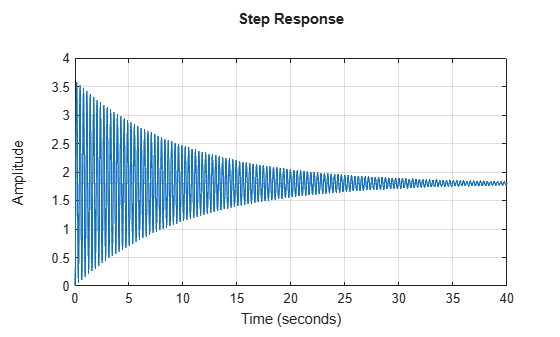

step(Gs)
grid on
xlim([0 40])

Part B

finalval = dcgain(Gs)

finalval = 1.8000

Part D

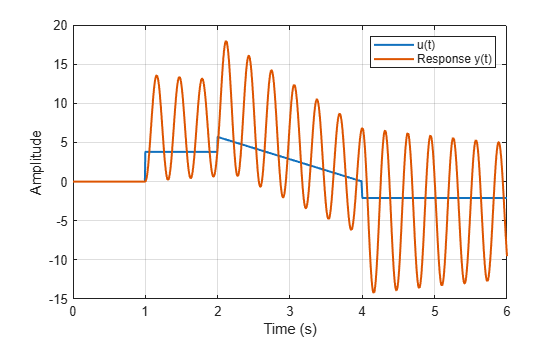



t = 0:0.001:6;

u = zeros(size(t));

u(t >= 1 & t < 2) = 3.8;

ramp = t >= 2 & t < 4;
u(ramp) = 5.7 - (5.7/2)*(t(ramp) - 2);

u(t >= 4) = -2.1;

Gs = tf(K*Wn^2, [1, 2*tau*Wn, Wn^2]);

y2 = lsim(Gs, u, t);

plot(t,u,'LineWidth',1.5);
hold on;
plot(t, y2, 'LineWidth', 1.5);
legend('u(t)', 'Response y(t)');
grid on;
xlim([0 6]);
xlabel('Time (s)');
ylabel('Amplitude');